# Lab - Initial value problems 2

**Topics: **4th order Runge-Kutta, solving higher order ODEs

## 1st order ODE

Integrate $\frac{\textrm{dy}}{\textrm{dt}}=4e^{0\ldotp 8t} -0\ldotp 5y$ from $t=0\;\textrm{to}\;1$ with step size, $h=1$.

Given initial value $y\left(t=0\right)=2$

dydt = @(t,y) 4*exp(0.8*t)-0.5*y;
t0 = 0;
tf = 1;
h = 1;
t_vals = t0:h:tf;
y0 = 2;

### Analytical solution

syms y(t)
ode = diff(y,t) == 4*exp(0.8*t)-0.5*y;
cond = y(t0) == y0;
yExact(t) = dsolve(ode, cond)

$$yExact(t) = \frac{2\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(20\,{\mathrm{e}}^{\frac{13\,t}{10}}-7\right)}{13}$$

### RK4 by hand

rk4_hand = zeros(size(t_vals));
rk4_hand(1) = y0;


$$k_1 =f\left(t_i ,y_i \right)$$


k1 = dydt(t_vals(1), rk4_hand(1))

k1 = 3


$$k_2 =f\left(t_{i+\frac{h}{2}} ,y_i +\frac{1}{2}k_1 h\right)$$


k2 = dydt(t_vals(1)+h/2, rk4_hand(1)+1/2*k1*h)

k2 = 4.2173


$$k_3 =f\left(t_{i+\frac{h}{2}} ,y_i +\frac{1}{2}k_2 h\right)$$


k3 = dydt(t_vals(1)+h/2, rk4_hand(1)+1/2*k2*h)

k3 = 3.9130


$$k_4 =f\left(t_i +h,y_i +k_3 h\right)$$


k4  =dydt(t_vals(2), rk4_hand(1)+k3*h)

k4 = 5.9457


$$\phi =\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)$$


phi = 1/6*(k1+2*k2+2*k3+k4)

phi = 4.2010

rk4_hand(2) = rk4_hand(1)+phi*h

rk4_hand =     2.0000    6.2010


### rk4sys

[t,y] = rk4sys(dydt, [t0, tf], y0, h/4)

t =          0    0.2500    0.5000    0.7500    1.0000


y =     2.0000
    2.8078
    3.7515
    4.8664
    6.1947


### Error

MPRTE = @(est, true) abs((true-est)/true)*100;
rk4Error = MPRTE(rk4_hand(2), double(yExact(t_vals(2))));
fprintf('The true error after one step is %6.4f%%', rk4Error);

The true error after one step is 0.1034%

## Higher order ODE

**Residence time:** $\tau =5\;\min$

**Rate constant for reaction of A to produce B: **$k=0\ldotp 12$ per minute

**Concentration of A at inlet of 1st reactor:** ${\textrm{CA}}_0 =20$

**All initial conditions:** 0

*Find concentrations every 30 sec. for the first 10 min.*

tau = 5;
k = .12;
CA0 = 20;
tspan = [0 10];
h = .5;
Z0 = [0 0 0 0];



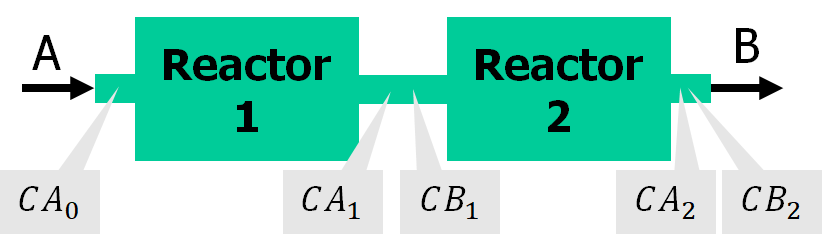

[t,z] = rk4sys(@dZdt, tspan, Z0, h, tau, k, CA0)

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


z =          0         0         0         0
    1.8482    0.0551    0.0900    0.0036
    3.4231    0.2023    0.3241    0.0263
    4.7652    0.4184    0.6579    0.0809
    5.9088    0.6848    1.0566    0.1744
    6.8834    0.9860    1.4939    0.3102
    7.7138    1.3100    1.9495    0.4885
    8.4215    1.6468    2.4085    0.7076
    9.0245    1.9889    2.8600    0.9642
    9.5384    2.3302    3.2961    1.2543


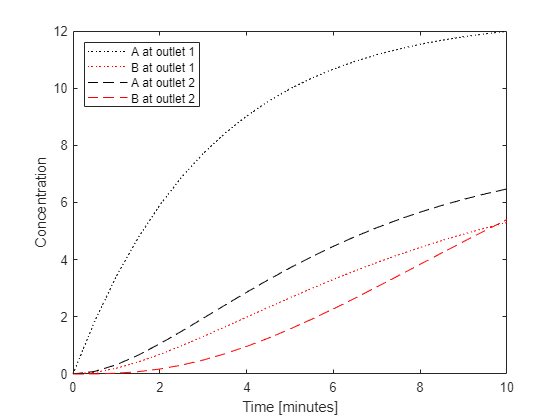

plot(t,z(:,1),"k:",t,z(:,2),"r:",t,z(:,3),"k--",t,z(:,4),"r--")
xlabel("Time [minutes]")
ylabel("Concentration")
legend("A at outlet 1", "B at outlet 1", "A at outlet 2", "B at outlet 2", "location", "northwest")

## Helper function


$$\frac{d}{\textrm{dt}}\left\lbrack Z\right\rbrack =\left\lbrack \begin{array}{c}
\frac{1}{\tau }\left(\left.{\textrm{CA}}_0 -Z\left(1\right)\right)-\textrm{kZ}\left(1\right)\right)\\
-\frac{1}{\tau }Z\left(2\right)+\textrm{kZ}\left(1\right)\\
\frac{1}{\tau }\left(\left.Z\left(1\right)-Z\left(3\right)\right)-\textrm{kZ}\left(3\right)\right)\\
\frac{1}{\tau }\left(\left.Z\left(2\right)-Z\left(4\right)\right)+\textrm{kZ}\left(3\right)\right)
\end{array}\right\rbrack$$


function dZ = dZdt(t,Z,tau,k,CA0)
dZ = [1/tau*(CA0-Z(1))-k*Z(1)
      -1/tau*Z(2)+k*Z(1)
      1/tau*(Z(1)-Z(3))-k*Z(3)
      1/tau*(Z(2)-Z(4))+k*Z(3)];
end